clear all 
close all

rho = 7829;
E = 206.940e9 ;
b = 0.05;
d = 0.1;
A = b * d;
I = (b*d^3)/12

I = 4.1667e-06

L = 5;
m_b = rho * L * A

m_b = 195.7250

m2 = 2 * m_b

m2 = 391.4500

m5 = 5 * m_b

m5 = 978.6250

m8 = 8 * m_b

m8 = 1.5658e+03


alpha = [1.87510407 4.69409113 7.85475744;
1.07619566 3.98257329 7.10265019;
0.87002146 3.94998049 7.08253760;
0.77687729 3.94137662 7.07735712] ;

w = alpha.^2 * sqrt( (E * I)/(rho * A)) /L^2 ;

f_eig = w/(2*pi)

f_eig =     3.3221   20.8191   58.2940
    1.0943   14.9860   47.6650
    0.7152   14.7417   47.3954
    0.5702   14.6776   47.3261


f_modes = [
3.47 21.70 60.59;
1.14 15.63 49.60;
0.747 15.39 49.38;
0.596 15.33 49.31;
]

f_modes =     3.4700   21.7000   60.5900
    1.1400   15.6300   49.6000
    0.7470   15.3900   49.3800
    0.5960   15.3300   49.3100



%analytical
f_eig_norm = f_eig .* (L^2 * (E*I / rho*A)^(-0.5))

f_eig_norm = 	1.0e+03 *

    0.1119    0.7014    1.9639
    0.0369    0.5049    1.6058
    0.0241    0.4966    1.5967
    0.0192    0.4945    1.5944



%NX
NX_eig_norm = f_modes .* (L^2 * (E*I / rho*A)^(-0.5))

NX_eig_norm = 	1.0e+03 *

    0.1169    0.7311    2.0412
    0.0384    0.5266    1.6710
    0.0252    0.5185    1.6636
    0.0201    0.5165    1.6612


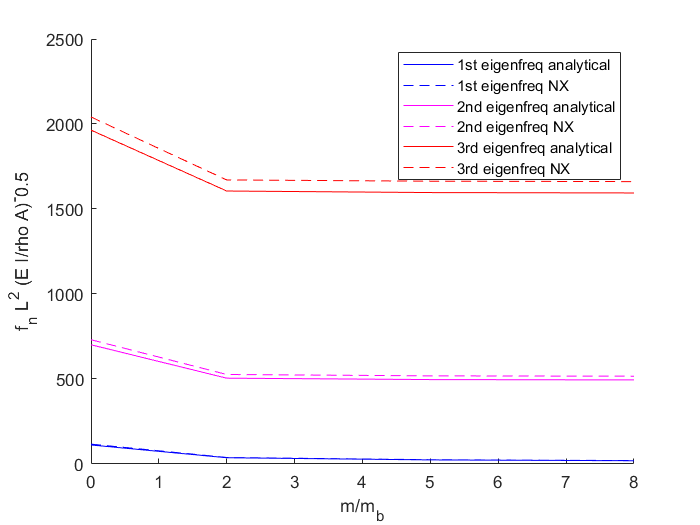


mmb = [0 2 5 8];

figure()  %2a
hold on
plot( mmb ,f_eig_norm(:,1), 'b')                 %first eigenfreq analytical
plot(mmb , NX_eig_norm(:,1), 'b--' )            %first eigenfreq nx
plot( mmb ,f_eig_norm(:,2), 'm')                 %second eigenfreq analytical
plot(mmb , NX_eig_norm(:,2),'m--' )             %etc
plot( mmb ,f_eig_norm(:,3), 'r')                 
plot(mmb , NX_eig_norm(:,3),'r--' )                         
xlabel('m/m_b')
ylabel('f_n L^2 (E I/rho A)^-0.5')
legend('1st eigenfreq analytical', '1st eigenfreq NX','2nd eigenfreq analytical', '2nd eigenfreq NX','3rd eigenfreq analytical', '3rd eigenfreq NX')





f_error = (f_modes - f_eig)

f_error =     0.1479    0.8809    2.2960
    0.0457    0.6440    1.9350
    0.0318    0.6483    1.9846
    0.0258    0.6524    1.9839


H = size(f_modes)

H =      4     3


f_er_perc = zeros(H);
for i=1:H(1)
    for j=1:H(2)
        f_er_perc(i,j) = f_error(i,j)/f_eig(i,j)*100;
    end
end
f_er_perc

f_er_perc =     4.4528    4.2313    3.9386
    4.1751    4.2972    4.0596
    4.4485    4.3975    4.1873
    4.5160    4.4450    4.1920


mean(mean(f_er_perc))

ans = 4.2784

mode1 = readtable("mode1.csv");

mode2 = readtable("mode2.csv");

mode3 = readtable("mode3.csv");

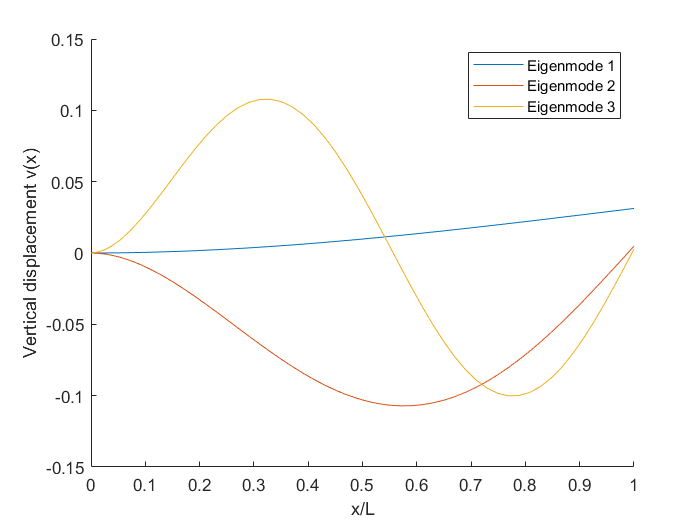

m1 = mode1.DisplacementAlongPath_1__SeriesOfNodes;
m2 = mode2.DisplacementAlongPath_2__SeriesOfNodes;
m3 = mode3.DisplacementAlongPath_3__SeriesOfNodes;

x = mode1.x_X/5000;
figure()
clf;
hold on
plot(x,m1)
plot(x,m2)
plot(x,m3)
xlabel('x/L')
ylabel('Vertical displacement v(x)')
legend('Eigenmode 1','Eigenmode 2','Eigenmode 3')

f_eig_mx= flip([0.747;
    0.817;
    0.881;
    0.995;
    1.04;
    1.13;
    1.24;
    1.37;
    1.52;
    1.69;
    1.89;
    2.12;
    2.38;
    2.66;
    2.95;
    3.20;
    3.38;
    3.48;
    3.52;
    3.53;
    3.53;
])

f_eig_mx =     3.5300
    3.5300
    3.5200
    3.4800
    3.3800
    3.2000
    2.9500
    2.6600
    2.3800
    2.1200



xL = [0:1/20:1]

xL =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


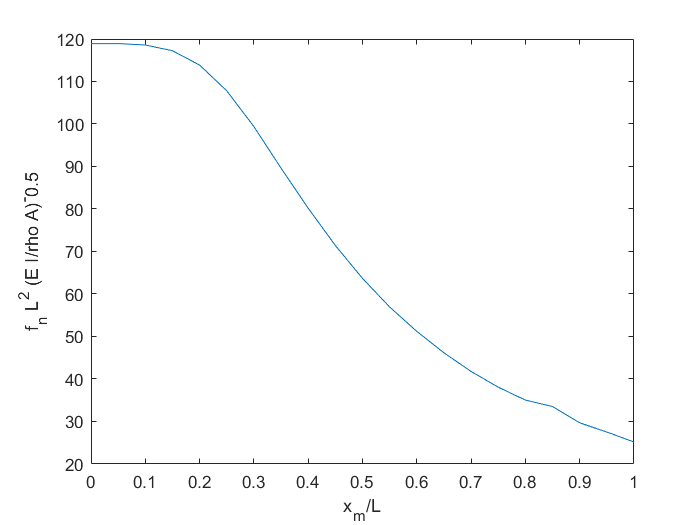

f_eig_mx_norm =  f_eig_mx .* (L^2 * (E*I / rho*A)^(-0.5));
figure()
clf;
plot(xL,f_eig_mx_norm)
ylabel('f_n L^2 (E I/rho A)^-0.5')
xlabel('x_m/L')